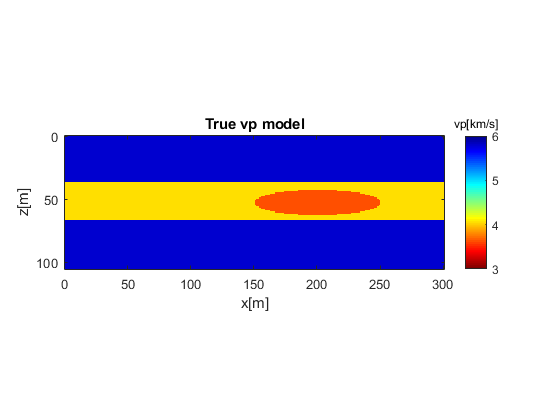

% read binary vp model data and plot it
path2model = 'E:/Geophysics/Project/Crosswell/FWI_2arr/vp22_elp';
%path2model = 'C:\DFiles\Geophysics\Project\Figs_Crosswell/vp22_elp';
nz=106; nx=301; dx=1; dz=1;
fid = fopen(path2model, 'r');
vp = fread(fid, [nz, nx], 'float32')/1000;
imagesc(dx*(0:nx), dz*(0:nz-1), vp, [3, 6]); 
colormap(flipud(jet));
axis equal; axis tight; 
cbar=colorbar; title(cbar, 'vp[km/s]');
title('True vp model'); xlabel('x[m]'); ylabel('z[m]');

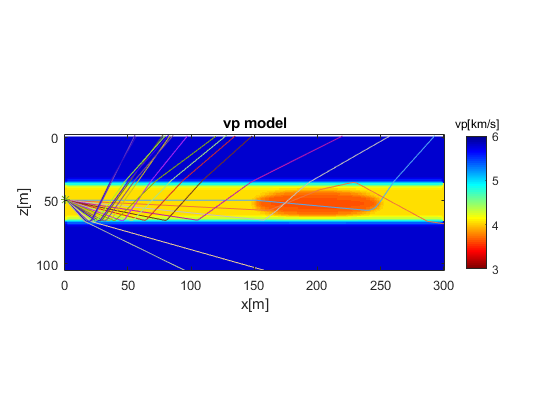

% smooth vp
vpsmooth = mysmooth(vp, 10);
imagesc(dx*(0:nx-1), dz*(0:nz-1), vpsmooth, [3, 6]); 
colormap(flipud(jet));
axis equal; axis tight; 
cbar=colorbar; title(cbar, 'vp[km/s]');
title('vp model'); xlabel('x[m]'); ylabel('z[m]');
hold on;
% rays
srcpos=[50;1];
for ang=0.:0.05:pi/2-asin(3.65/5.8) % the range of take-off angles of the rays from the source point
    p=[sin(ang);cos(ang)]; % ray parameter
    [rayx, rayz, rays, rayt]=tracer(vp, dx, dz, p, srcpos, 20000); %ray tracing
    plot(dx*rayx, dz*(rayz),'color',[rand rand rand], 'LineWidth', 1); % ploting the ray
end
plot(dx*srcpos(2), dz*srcpos(1)-1, '*');
hold off;

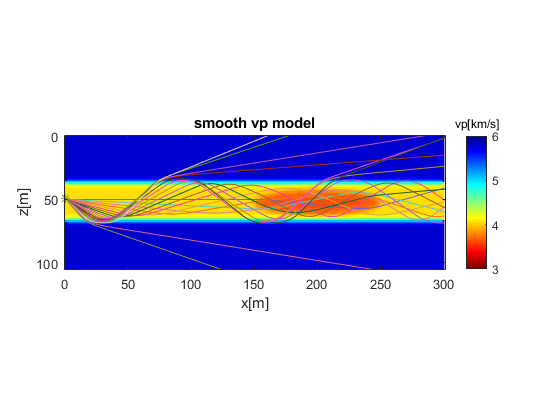

imagesc(dx*(0:nx-1), dz*(0:nz-1), vpsmooth, [3, 6]);
axis equal; axis tight; 
cbar=colorbar; title(cbar, 'vp[km/s]');
title('smooth vp model'); xlabel('x[m]'); ylabel('z[m]');
hold on;
for ang=0.:0.05:pi/2-asin(3.65/5.8) % the range of take-off angles of the rays from the source point
    p=[sin(ang);cos(ang)]; % ray parameter
    [rayx, rayz, rays, rayt]=tracer(vpsmooth, dx, dz, p, srcpos, 20000); %ray tracing
    plot(dx*rayx, dz*(rayz),'color',[rand rand rand], 'LineWidth', 1); % ploting the ray
end
plot(dx*srcpos(2), dz*srcpos(1)-1, '*');
hold off;

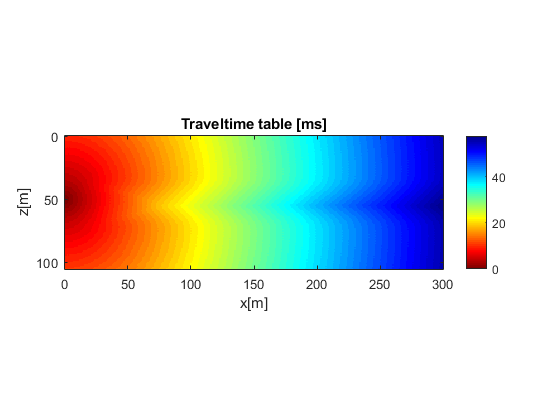

srcx1=50; % source z position
srcx2=0;% source x position
h=dx;
% pad vp model for time table calculation
pad=2;
vppad = padarray(vpsmooth, [pad pad], 'replicate','both' );
n1=nz+2*pad;
n2=nx+2*pad;
srcx1=pad+srcx1; 
srcx2=pad+srcx2;
sln=1./vppad;
% calculating traveltime table
ttemp=tt(sln, n1, n2, h, srcx1, srcx2);
ttbl=mysmooth(ttemp,0);
imagesc(h*((0:nx-1)), h*((0:nz-1)), ttbl(pad:pad+nz-1, pad:pad+nx-1)); 
colorbar;axis equal;axis tight;
xlabel('x[m]');ylabel('z[m]');
title('Traveltime table [ms]');

recx1=60; % receiver z-position
recx2=srcx2+nx-1-pad;% receiver x-position
% pad
recx1=recx1+pad; 
recx2=recx2+pad;
dtdz=diff(ttbl, 1, 1);
dtdz=[dtdz; dtdz(n1-1,:)];
dtdx=diff(ttbl, 1, 2);
dtdx=[dtdx dtdx(:,n2-1)];
[nz1, nx1]=size(dtdz);
[X, Z]=meshgrid(0:nx1-1, 0:nz1-1);
[Xq, Zq]=meshgrid(0:0.5:nx1-1,0:0.5:nz1-1);
%dtdz1=interp2(X,Z,dtdz,Xq,Zq);
x=[recx1; recx2];
nitr=500;
path=zeros(nitr, 2);
for itr=1:nitr-1
    path(itr, :)=x;
    %ix1=int32(x(1));
    %ix2=int32(x(2));
    if(abs(x(1)-srcx1)<2 && abs(x(2)-srcx2)<2); break; end
    %g=[dtdz(ix1, ix2) dtdx(ix1, ix2)];
    g=[interp2(X,Z,dtdz,x(2),x(1)), interp2(X,Z,dtdx,x(2),x(1))];
    dx=g';
    %dr=g*dx;
    alpha=-2;%% fixed step length
    while(1)
        x0=x+alpha*dx/norm(dx);
        if(x0(1)<1 || x0(2)<1)
            alpha=alpha*0.5;
        else
            break;
        end
    end
    x=x+alpha*dx/norm(dx);
end
path(itr+1, :)=[srcx1 srcx2];

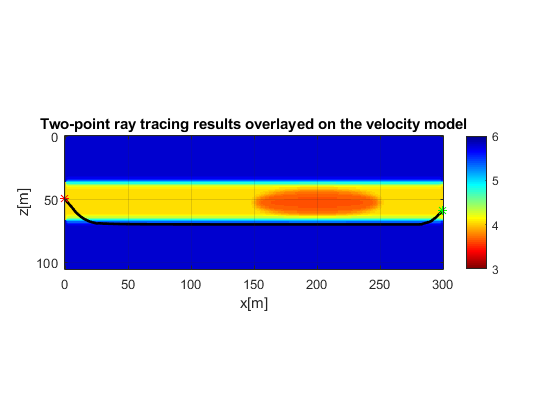

imagesc(h*((0:nx-1)), h*((0:nz-1)), vpsmooth,[3,6]);
colormap(flipud(jet)); axis tight; axis equal;
colorbar;
hold on;
plot(h*(path(1:itr,2)-pad-1), h*(path(1:itr,1)-pad-1), 'color', [0 0 0], 'LineWidth', 2);
plot(h*(srcx2- pad -1), h*(srcx1-pad-1), 'r*');
plot(h*(recx2-pad-1), h*(recx1-pad-1), 'g*');
hold off;
grid;
xlabel('x[m]');
ylabel('z[m]');
title('Two-point ray tracing results overlayed on the velocity model');

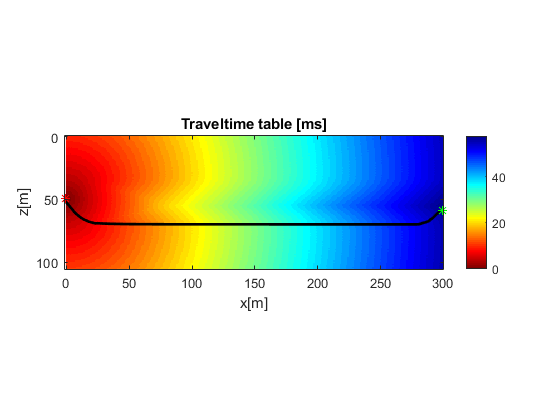

imagesc(h*((0:nx-1)), h*((0:nz-1)), ttbl(pad:pad+nz-1, pad:pad+nx-1)); 
colorbar;axis equal;axis tight;
xlabel('x[m]');ylabel('z[m]');
title('Traveltime table [ms]');
hold on;
plot(h*(path(1:itr,2)-pad-1-pad), h*(path(1:itr,1)-pad-1), 'color', [0 0 0], 'LineWidth', 2);
plot(h*(srcx2- pad -1), h*(srcx1-pad-1), 'r*');
plot(h*(recx2-pad-1), h*(recx1-pad-1), 'g*');
hold off;